سوال1 الف

x = 0.75;
func = 0;
i = 0;
term = 1;
while (exp(0.75) *term) > 0.000005 
    func = func + term;
    i = i+1;
    term = x^i / factorial(i);
end
disp('Number of steps:')

Number of steps:


disp(i)

     9



disp('Value of function:')

Value of function:


sprintf('%0.5f',func)

ans = '2.11700'

سوال1 ب

x = pi/3;
func = 0;
for i = 0:4
    term = x^i / factorial(i);
    func = func + term;
end
disp('Value of function:')

Value of function:


sprintf('%0.5f',func)

ans = '2.83701'

سوال2 الف

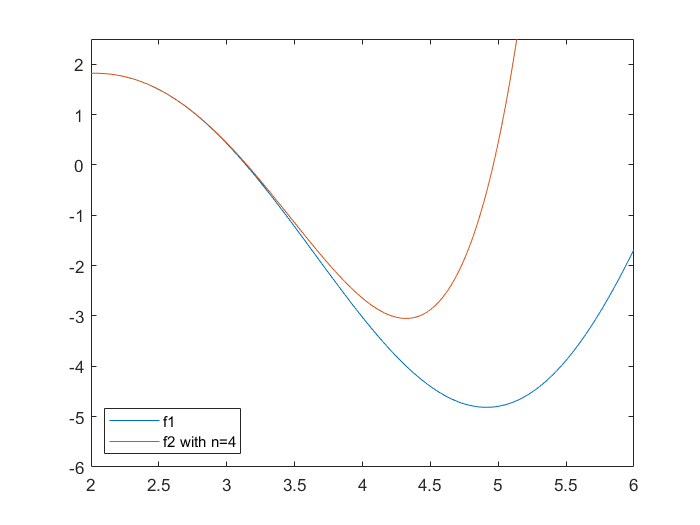

x = 2:0.001:6;
f1 = x.*sin(x);
f2_1 = calc_f(x,4);
f2_2 = calc_f(x,6);
f2_3 = calc_f(x,8);
plot_f1_f2(x,f1,f2_1,4)

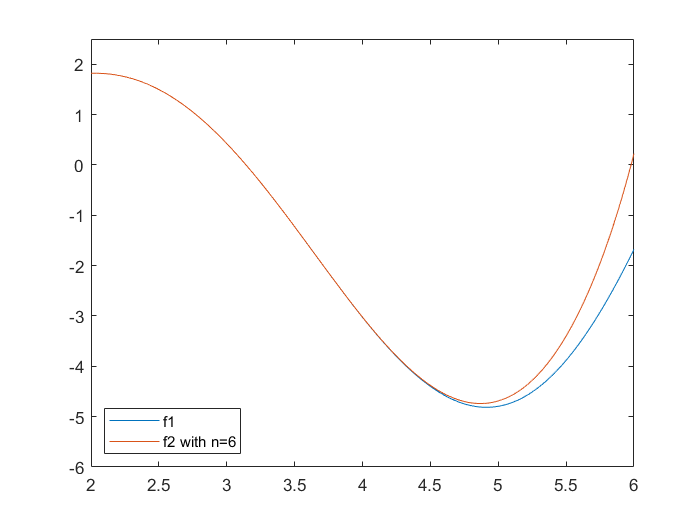

plot_f1_f2(x,f1,f2_2,6)

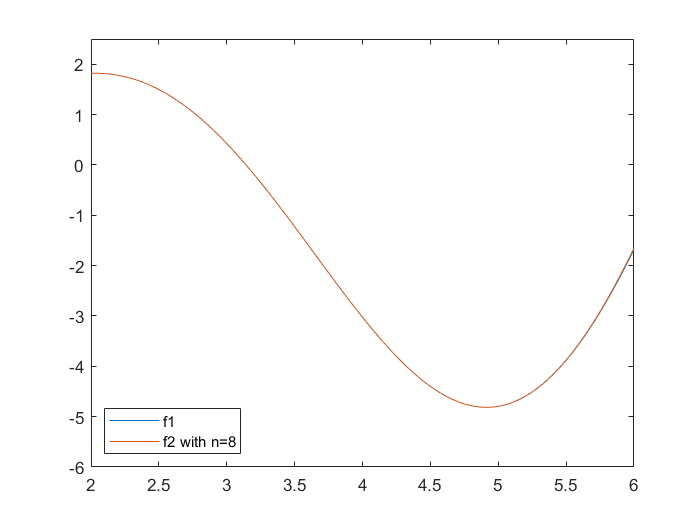

plot_f1_f2(x,f1,f2_3,8)

سوال2 ب

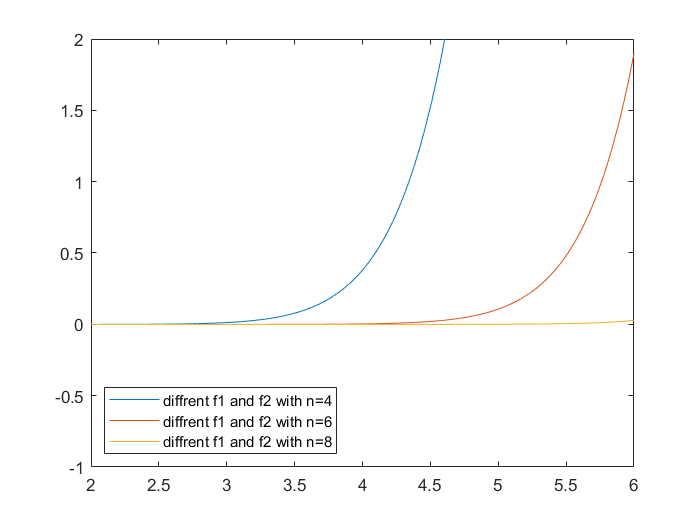

x = 2:0.001:6;
f1 = x.*sin(x);
f2_1 = calc_f(x,4);
f2_2 = calc_f(x,6);
f2_3 = calc_f(x,8);
f_diff_1 = abs(f1 - f2_1);
f_diff_2 = abs(f1 - f2_2);
f_diff_3 = abs(f1 - f2_3);
plot(x, f_diff_1)
hold on
plot(x, f_diff_2)
plot(x, f_diff_3)
ylim([-1 2]);
legend('diffrent f1 and f2 with n=4','diffrent f1 and f2 with n=6', ...
    'diffrent f1 and f2 with n=8','Location','southwest')
hold off

سوال 3

syms x y z;
x0 = 1;
y0 = 2;
z0 = 3;
r = @(x,y,z) sqrt(x^2 + y^2 + z^2);
diff_r(x,y,z) = diff(r,x) + diff(r,y) + diff(r,z);
error = 1 / eval(diff_r(x0,y0,z0));
disp('Maximum value for e:')

Maximum value for e:


disp(error)

    0.6236



توابع برای سوال2

function plot_f1_f2(x,f1,f2,n)
    plot(x, f1)
    hold on;
    plot(x, f2)
    ylim([-6 2.5]);
    legendInfo = sprintf('f2 with n=%d', n);
    legend('f1',legendInfo,'Location','southwest')
    hold off
end

function f = calc_f(x,n)
    f = zeros(size(x));
    for i = 0:n
        f = f + ((-1)^i)*x.^(2*i+2)./factorial(2*i + 1);
    end
end 